# Molico (2006) Replication

## Calibration

clear all
close all
clc

tic

mupper=700 %highest value if money holdings on the grid

mupper = 700

N=1000 %number of agents for simulating distribution

N = 1000

iterations=40 %maximum number of iterations for the value function iteration    

iterations = 40

stopping_parameter=0.01 %the smaller, the more does it iteration take to converge

stopping_parameter = 0.0100

x=0.1

x = 0.1000

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=100 %Money supply

M = 100

r=1/beta-1 %real interest rate

r = 0.0101

mu=0 %Money Growth

mu = 0

smoothing_parameter=0.3

smoothing_parameter = 0.3000

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
% grids_1=5
% 
% grids_2=7
% grids_3=5
% grids=grids_1+grids_2+grids_3
% 
% m_0=linspace(0,80,grids_1)
% m_1=linspace(90,200, grids_2)
%  m_2=linspace(220,mupper,grids_3);
%  m=[m_0,m_1,m_2]
grids=20

grids = 20

m=linspace(0,mupper, grids)

m =          0   36.8421   73.6842  110.5263  147.3684  184.2105  221.0526  257.8947  294.7368  331.5789  368.4211  405.2632  442.1053  478.9474  515.7895  552.6316  589.4737  626.3158  663.1579  700.0000


## Options



test_interpolation=0; % checks the interpolation method and displays the initial guess of the value function
test_utility=0; % displays the utility and cost function
display_plot_V=1;
display_plot_q=1;
display_plot_d=1;
display_plot_meeting=0;
display_plot_Distribution_rough=0;
display_plot_Distribution_smooth=1;
display_plot_cdf=0;
display_plot_money_savings=0;
display_plot_M_Track_1=0;






## set up matrixes

initial_distribution_shock=ones(1,N);
Distribution_number=ones(1,N);
Distribution_0=ones(1,N);
cdf_0=zeros(1,grids);
lamdba_0=zeros(1,grids);
m_savings_1=zeros(1,grids)

m_savings_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m_savings_2=zeros(1,grids)

m_savings_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m_savings_3=zeros(1,grids)

m_savings_3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end



M_0=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf_0(1,1)=lamdba_0(1,1);
cdf_0(1,i+1)=cdf_0(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf_0(1,l)
Distribution_number(1,i)=l;
Distribution_0(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end

 


## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

 [V,q,d,Distribution,lamdba,cdf,M_track_1, M_track_2,Meeting,i] = Iter_Molico_06(iterations, N,m...
     ,grids,V0,lamdba_0, cdf_0,Distribution_0,M_0,r,alpha,x,mu,theta,mupper, stopping_parameter,0)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 20


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 21


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 22


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 23


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 24


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 25


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 26


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 27


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 28


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 29


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 30


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0         0


Value function has not converged


i = 31


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0         0


Value function has not converged


i = 32


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0         0


Value function has not converged


i = 33


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0         0


Value function has not converged


i = 34


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0         0


Value function has not converged


i = 35


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0         0


Value function has not converged


i = 36


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0         0


Value function has not converged


i = 37


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0         0


Value function has not converged


i = 38


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053         0


Value function has not converged


i = 39


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053


Value function has not converged


i = 40

V =     0.0000  363.7846  462.9724  495.0759  519.1015  538.6787  554.1032  566.8745  577.8209  587.3662  595.8221  603.4094  610.2864  616.5726  622.3598  627.7201  632.7112  637.3798  641.7646  645.8974


q =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9178    0.8576    0.7086    0.6321    0.6034    0.5577    0.5137    0.4780    0.4451    0.4147    0.3869    0.3611    0.3370    0.3146    0.2934    0.2736    0.2548    0.2371    0.2202    0.0000
    0.9598    0.9282    0.8468    0.8063    0.7880    0.7597    0.7327    0.7100    0.6885    0.6682    0.6494    0.6315    0.6146    0.5986    0.5833    0.5687    0.5547    0.5413    0.5285    0.0000
    0.9694    0.9452    0.8849    0.8580    0.8442    0.8236    0.8046    0.7884    0.7729    0.7583    0.7446    0.7315    0.7191    0.7072    0.6958    0.6849    0.6743    0.6641    0.6543    0.0000
    0.9716    0.9488    0.8925    0.8683    0.8553    0.8364    0.8193    0.8047    0.7907    0.7777    0.7655    0.7539    0.7429    0.7323    0.7222    0.7126    0.7032    0.6943    0.6856  

d =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.7244    1.1750    2.0903    2.4756    2.5723    2.7121    2.8225    2.8833    2.9170    2.9289    2.9219    2.8992    2.8632    2.8158    2.7584    2.6922    2.6184    2.5377    2.4507         0
    1.5652    2.5907    4.8890    6.0251    6.3578    6.8943    7.4043    7.7837    8.1116    8.3986    8.6456    8.8609    9.0495    9.2148    9.3600    9.4874    9.5992    9.6971    9.7825         0
    2.0910    3.5180    6.9466    8.7862    9.3532   10.2955   11.2238   11.9443   12.5920   13.1805   13.7076   14.1863   14.6233   15.0237   15.3919   15.7316   16.0459   16.3370   16.6080         0
    2.2564    3.7968    7.5400    9.5913   10.2340   11.3140   12.3928   13.2435   14.0196   14.7349   15.3848   15.9834   16.5376   17.0525   17.5327   17.9817   18.4030   18.7987   19.1723  

Distribution =   116.2134  120.9089  109.8382   84.5774  145.6064   87.4979   94.4844   93.1195  161.1529   74.1317  128.9879  141.3346   67.0589  119.8318  103.8768  131.7143  104.7098  133.2502   52.5114  140.2568   97.3941  100.7590  152.9037   83.7495  106.1478  179.7810   43.6250  139.4911  110.4252   73.8791  103.4238  125.7030  102.4664  111.7202   94.7879  162.4212   81.0682  109.9638  113.4624  109.4533  119.6192  105.8048  129.1892   86.6677   82.9352   89.8796  121.5889  200.1544   82.2189   59.3293


lamdba =          0    0.0020    0.0930    0.4150    0.3780    0.1030    0.0090         0         0         0         0         0         0         0         0         0         0         0         0         0


cdf =          0    0.0020    0.0950    0.5100    0.8880    0.9910    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 1×40
  116.5684  120.5105  123.2737  125.0789  126.5895  127.2158  128.2474  128.3947  128.5421  128.8368  128.9105  129.2053  129.3158  129.2421  129.0579  128.8737  128.7263  128.5789  128.8000  129.6105  129.3526  129.1684  128.7263  128.2474  129.0211  129.0211  128.4316  128.6895  128.7632  128.5421


M_track_2 = 1×40
1.0e+05 *

    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053    1.1053


Meeting = 1×1000
     4     5     4     4     4     5     5     5     5     5     4     5     6     5     5     4     4     6     6     5     4     5     3     5     5     3     3     6     6     4


i = 0


 if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
 end

cdf adds up to one


 last_iteration=i


## Plots

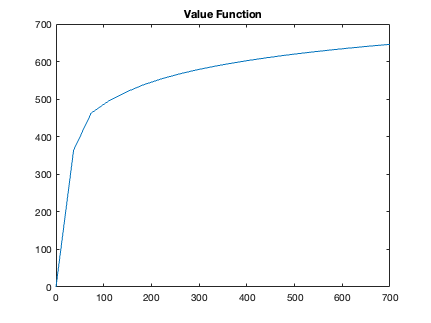

%Plot V
 if display_plot_V==1
figure(1)
plot(m,V)
title('Value Function')

 end

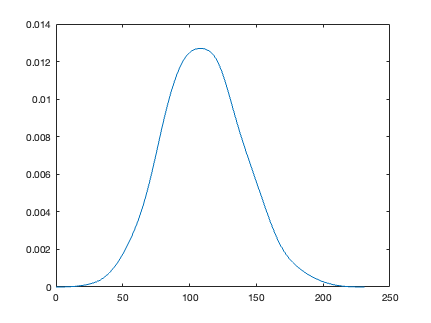



%Plot Distribution Smooth
if display_plot_Distribution_smooth==1 
    for i=1:N
    if Distribution(1,i)==0;
        Distribution(1,i)=0.001;
    end
    end

[f,xi] = ksdensity(Distribution,'Support','positive','BoundaryCorrection'...
    ,'reflection','Bandwidth',std(Distribution)*smoothing_parameter); 

figure(2)
plot(xi,f)
 end

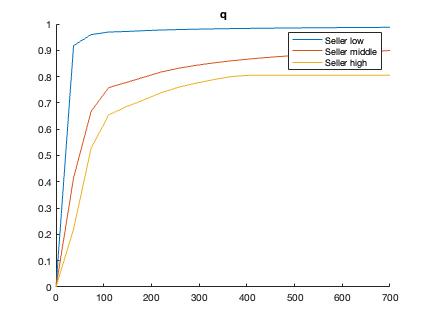




%Plot Distribution Rough
if display_plot_Distribution_rough==1
figure(3)
histogram(Distribution,grids*2)
 title('Distribution of Money holdings')
 end




%Plot q
 if display_plot_q==1
figure(4)
hold on
plot(m,q(:,1))
plot(m,q(:,round(grids/2)))
plot(m,q(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')
 end

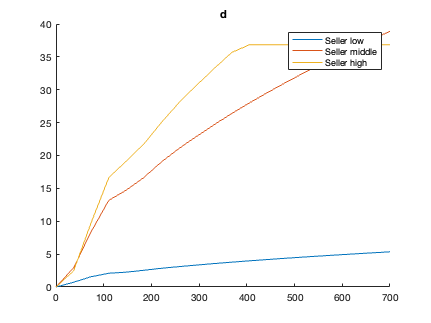





%Plot d
 if display_plot_d==1
figure(5)
hold on
plot(m,d(:,1))
plot(m,d(:,round(grids/2)))
plot(m,d(:,grids-1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')
 end


%Plot cdf
if display_plot_cdf==1
figure (6)
plot(m,cdf)
title('cdf')
end


% Plot Money Savings
if display_plot_money_savings==1
m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')
end



% Plot Mettings
if display_plot_meeting==1
for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end
figure (8)
histogram(Meeting,grids)
title('Meetings of agents')
end



%Plot M_track_1
if display_plot_M_Track_1==1
index=[1:iterations]
figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')
end


toc

Elapsed time is 143.301651 seconds.


Unrecognized function or variable 'last_iteration'.